close("all"); clear; clc;
setmadsympath();

## Parameters

bs = bigSportsParameters;
s2m = @(x)cell2mat(struct2cell(x));
disp(bikeSimToPrydeParameters(bs,80/3.6));

    Cdelta: 12.6738
      Ibxx: 19.4758
      Ibxz: -1.4841
      Ibzz: 31.0846
      Ihxx: 1.9740
      Ihzz: 0.5372
         v: 22.2222
        Zf: 1.4012e+03
        Zr: 1.3574e+03
         a: 0.5998
       af0: 0.0200
        an: 0.0882
       ar0: 0.0200
         b: 0.7271
         e: 0.0253
         f: 0.3024
       fw0: 0.0216
       fw2: 1.1606e-06
         g: 9.8066
         h: 0.5750
       ify: 0.4840
       iry: 0.6380
       kaf: 11
       kar: 11
       kkf: 10
       kkr: 10
       klf: 1
       klr: 1
        mb: 257.0600
        mh: 24.2400
        rf: 0.2320
        rr: 0.2270
        tf: 0.0500
        tr: 0.0700
    caster: 0.4189



params = @(v)s2m(bikeSimToPrydeParameters(bs,v));

## Model

nv = 1000;
vx = linspace(30,130,nv)./3.6;
plant = @prydeMotorcycleLateralStateSpace;
f = @(v)plant(params(v));
sys = arrayfun(f,vx.',"uniform",0);

## Nyquist plot

poles = cellfun(@pole,sys,"uniform",0);
poles = cell2mat(poles);

Plot poles over speed :

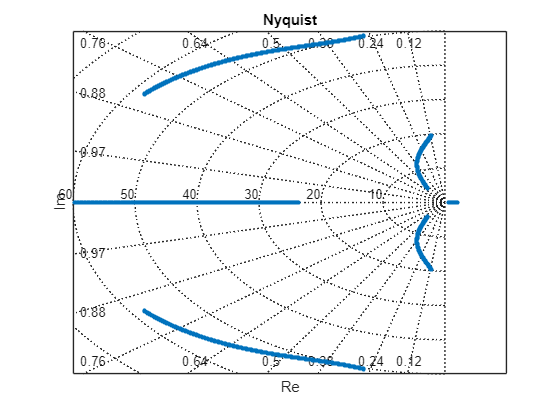

fig = figure();
axe = axes(fig);

scatter(axe,real(poles),imag(poles), ...
    10, ...
    "filled" ...
    );

xticks(axe,[]);
yticks(axe,[]);
title(axe,"Nyquist");
xlabel(axe,"Re");
ylabel(axe,"Im");
box(axe,"on");
sgrid(axe);

## BikeSim results

vx = 80;
n2s = @num2str;
load("G:\My Drive\BikeSimResults\BigSports\OpenLoop80Kph\results_big_sports_open_loop_80kph.mat");

time = results.Time;
camber = results.Roll;
steer = results.Steer;
wz = results.AVz;
vy = results.VyW0_2./3.6;
wx = results.AVx;
ws = -results.M_StrSys./0.2212;

s = (180/pi).*[1,1,1,0,1,1] + [0,0,0,1,0,0];
x_mes = [camber,steer,wz,vy,wx,ws];

Mz = results.M_Str_In;

## Model results

sys = plant(params(vx));
x_sys = s.*lsim(sys,[0.*Mz,Mz],time);

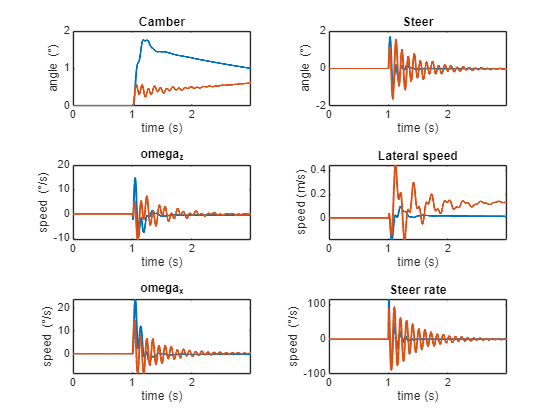

fig = figure();
tl = tiledlayout(3,2,"Parent",fig);

titles = [
    "Camber";
    "Steer";
    "omega_z";
    "Lateral speed";
    "omega_x";
    "Steer rate"
    ];

units = [
    "angle (\circ)";
    "angle (\circ)";
    "speed (\circ/s)";
    "speed (m/s)";
    "speed (\circ/s)";
    "speed (\circ/s)"
    ];

for k = 1:6
    axe = nexttile(k);
    hold(axe,"on");
    plot(axe,time,x_mes(:,k),"LineWidth",1.5);
    plot(axe,time,x_sys(:,k),"LineWidth",1.5);
    hold(axe,"off");
    xlim(axe,[0,time(end)]);
    box(axe,"on");
    title(axe,titles(k));
    xlabel(axe,"time (s)");
    ylabel(axe,units(k));
end